# Denoising Work Flow

## Add Files

addpath 'GT Folder'
addpath 'Real Noisy Images Folder'
addpath 'Common Functions'
addpath 'Models'

## Load Image

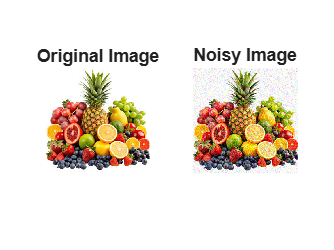

Image_name = 'fruits_imageGT.png';
%Image_name = 'balloons_noisy.png';

GT_substring = contains(Image_name, 'GT');
% Initialization
d = 8; % depth of the n/w
imsize = -1;

if GT_substring
    % Get the ground truth image
    I = imread(fullfile('GT Folder', Image_name));
    img = imresize(I, [256 256]);
    % Add noise to the image
    noisyImg = imnoise(img, 'gaussian', 0, 0.01); % Add Gaussian noise to the image
    % Display the original and noisy images for comparison
    figure;
    subplot(1, 2, 1), imshow(img), title('Original Image');
    subplot(1, 2, 2), imshow(noisyImg), title('Noisy Image');

elseif ~GT_substring
    % Load noisy image
    I = imread(fullfile('Real Noisy Images Folder', Image_name));
    noisyImg = imresize(I, [256 256]);
    % Display the loaded noisy image
    figure;
    imshow(noisyImg), title('Loaded Noisy Image');
else
    assert(false, 'File Path or File name invalid')
end

## Define CNN and Noise Tensor

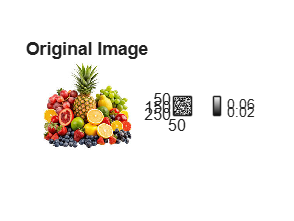

% --- Create Noise Tensor ---
input_depth = 3;
method = 'noise';
spatial_size = size(noisyImg, 1);
net_input = get_noise(input_depth, method, spatial_size);

%Visualize Noise
imagesc(net_input(:,:,2))
axis image
colormap gray
colorbar


% --- Create CNN ---
num_layers = d;
num_channels = 64;
num_classes = 3;
kernel_size = 3;
[a, b, ~] = size(noisyImg);
imgSize = [a, b, input_depth]; % Set the image size for the CNN

%net = buildCNN(num_layers, num_channels, kernel_size, imgSize, input_depth);
net = DipUnet3(imgSize, num_classes);
%net = InpaintUnet3(imgSize, num_classes);

% Compute number of parameters
totalParams = 0;
lrnables = net.Learnables;
for i = 1:height(lrnables)
    param = lrnables.Value{i};
    totalParams = totalParams + numel(extractdata(param));
end
fprintf('Number of params: %d\n', totalParams);

Number of params: 737035



% --- Define The Loss Function ---
%loss = mean((out - img_noisy).^2,'all');


function loss = computeLoss(out, img_noisy, lambda_tv) 
 
mse_loss = mean((out - img_noisy).^2, 'all'); 
%Total Variation: penalise spatial gradients in output 
dx = out(:, 2:end, :, :) - out(:,1:end-1, :, :); 
dy = out(2:end, :, :, :) - out(1:end-1, :, :, :); 
tv_loss = mean(abs(dx),'all') + mean(abs(dy), 'all'); 
loss = mse_loss + lambda_tv * tv_loss; 
end 
% Suggested: lambda_tv = 1e-4 to 1e-3 (tune for noise level)

## Optimization Step 1

function [loss, gradients, out, out_avg] = modelGradients(net, net_input_saved, img_noisy, out_avg, exp_weight, reg_noise_std)

    img_noisy = dlarray(img_noisy,'SSCB');

    if reg_noise_std > 0
        noise = randn(size(extractdata(net_input_saved)), 'single');
        noise = dlarray(noise, 'SSCB');
        net_input = net_input_saved + noise*reg_noise_std;
    else
        net_input = net_input_saved;
    end

    % Forward pass
    out = forward(net, net_input);

    % Loss (MSE)
    loss = mean((out - img_noisy).^2,'all');
    %loss = computeLoss(out, img_noisy, 1e-32);

    % Output smoothing (detach)
    out_detached = dlarray(extractdata(out),'SSCB');

    if isempty(out_avg)
        out_avg = out_detached;
    else
        out_avg = out_avg*exp_weight + out_detached*(1-exp_weight);
    end

    % Gradients
    gradients = dlgradient(loss, net.Learnables);

end

## Optimization Step 2

Iteration 00001 Loss 0.171627 PSNR_noisy: 7.6541 PSNR_gt: 7.3591 PSNR_gt_sm: 7.3591
Iteration 00002 Loss 0.166712 PSNR_noisy: 7.7803 PSNR_gt: 7.4806 PSNR_gt_sm: 7.3686
Iteration 00003 Loss 0.170234 PSNR_noisy: 7.6895 PSNR_gt: 7.3969 PSNR_gt_sm: 7.3773
Iteration 00004 Loss 0.170463 PSNR_noisy: 7.6837 PSNR_gt: 7.3832 PSNR_gt_sm: 7.3845
Iteration 00005 Loss 0.159218 PSNR_noisy: 7.9801 PSNR_gt: 7.6768 PSNR_gt_sm: 7.3955
Iteration 00006 Loss 0.163846 PSNR_noisy: 7.8556 PSNR_gt: 7.5601 PSNR_gt_sm: 7.4057
Iteration 00007 Loss 0.160327 PSNR_noisy: 7.9499 PSNR_gt: 7.6469 PSNR_gt_sm: 7.4155
Iteration 00008 Loss 0.160955 PSNR_noisy: 7.9330 PSNR_gt: 7.6354 PSNR_gt_sm: 7.4252
Iteration 00009 Loss 0.161557 PSNR_noisy: 7.9167 PSNR_gt: 7.6127 PSNR_gt_sm: 7.4346
Iteration 00010 Loss 0.164291 PSNR_noisy: 7.8439 PSNR_gt: 7.5468 PSNR_gt_sm: 7.4433
Iteration 00011 Loss 0.156678 PSNR_noisy: 8.0499 PSNR_gt: 7.7471 PSNR_gt_sm: 7.4543
Iteration 00012 Loss 0.159259 PSNR_noisy: 7.9790 PSNR_gt: 7.6810 PSNR_gt_sm:

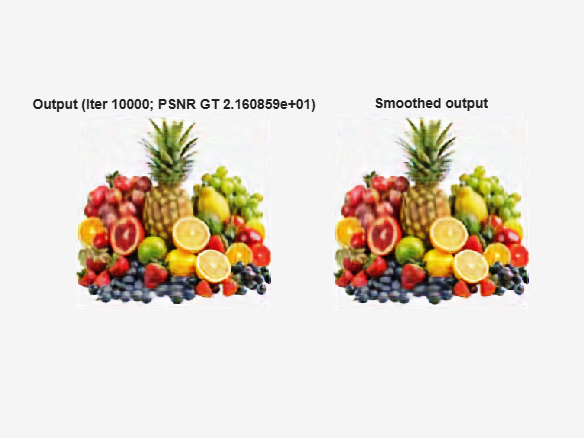

trailingAvg   = [];
trailingAvgSq = [];
reg_noise_std = 1/30;

if GT_substring
    img_gt = img;
    img_gt = im2double(img_gt);
end

PLOT = 1; % 1 for plotting and 0 otherwise
LR = 1e-4;
show_every = 10;
exp_weight = 0.99;
num_iter = 10000;
out_avg = [];
last_net = [];
last_learnables = [];
psrn_noisy_last = 0;
psnr_noisy_last = -inf;


noisyImg_nom = im2double(noisyImg);

% Convert net_input to dlarray format
%net_input = dlarray(net_input, 'SSCB');
%net_input_saved = dlarray(net_input, 'SSCB');
net_input_saved = dlarray(single(net_input), 'SSCB');

% --- Training Loop ---
for iter = 1:num_iter
    % Call function for forward pass
    [loss, gradients, out, out_avg] = dlfeval(@modelGradients, net, net_input_saved, noisyImg_nom, out_avg, exp_weight, reg_noise_std);
    
    
    [net, trailingAvg, trailingAvgSq] = adamupdate(net, gradients,trailingAvg, trailingAvgSq, iter, LR);
    

    % --- Convert dlarray to numeric ---
    out_num = double(gather(extractdata(out)));
    out_num = out_num(:,:,:,1);
    out_avg_num = double(gather(extractdata(out_avg)));
    out_avg_num = out_avg_num(:,:,:,1);

    noisyImg_num = im2double(noisyImg);

    %--- Compute PSNR ---
    psnr_noisy = psnr(out_num, noisyImg_num);
    if GT_substring
        img_numGT = im2double(img_gt);
        psnr_gt = psnr(out_num, img_numGT);
        psnr_gt_sm = psnr(out_avg_num, img_numGT);
        % --- Print Loss and PSNR ---
        fprintf('Iteration %05d Loss %.6f PSNR_noisy: %.4f PSNR_gt: %.4f PSNR_gt_sm: %.4f\r', iter,gather(extractdata(loss)),...
        psnr_noisy, psnr_gt, psnr_gt_sm);
    else
        % --- Print Loss and PSNR ---
        fprintf('Iteration %05d Loss %.6f PSNR_noisy: %.4f\r', iter,gather(extractdata(loss)),...
        psnr_noisy);
    end
    
    % --- Start Plotting ---
    if PLOT && mod(iter, show_every) == 0
        % Clip to [0, 1]
        out_plt = min(max(out_num, 0), 1);
        out_avg_plt = min(max(out_avg_num, 0), 1);
        % Plot side by side
        fig = figure(1); clf
        set(fig, 'Visible', 'on');
        subplot(1,2,1);
        imagesc(out_plt); colormap gray; axis image off;
        if GT_substring
            title(sprintf('Output (Iter %d; PSNR GT %d)', iter,psnr_gt));
        else
            title(sprintf('Output (Iter %d; PSNR Noisy %d)', iter,psnr_noisy));
        end

        subplot(1,2,2);
        imagesc(out_avg_plt); colormap gray; axis image off;
        title('Smoothed output')
        drawnow 
    end

    % --- Back Tracking Logic ---
    if  mod(iter, show_every) ~= 0
        if psnr_noisy - psnr_noisy_last < -5
            fprintf('\n Falling back to previous checkpoint.\n');
            % Restore weights
            net.Learnables.Value = last_learnables;
            break; % stop training
        else
            % Save current weights
            last_learnables = net.Learnables.Value;
            psnr_noisy_last = psnr_noisy;
        end
    end

end

## Save Weights

% Convert Learnables table to standard numeric values for simple MAT storage
net_weights = net.Learnables;
for k = 1:height(net_weights)
    if isdlarray(net_weights.Value{k})
        net_weights.Value{k} = gather(extractdata(net_weights.Value{k}));
    end
end

% Clip output image to valid [0, 1] range
final_image = min(max(out_avg_num, 0), 1);

mat_filename = 'saved_model_and_image_denoising.mat'

mat_filename = 'saved_model_and_image_denoising.mat'


% Save network object, extracted weights table, and final output image
save(mat_filename, 'net', 'net_weights', 'final_image');

imwrite(final_image, 'output_image_denoised.png');

fprintf('\nSuccessfully saved weights and image to %s\n', mat_filename);


Successfully saved weights and image to saved_model_and_image_denoising.mat


## Load and Use Saved Data

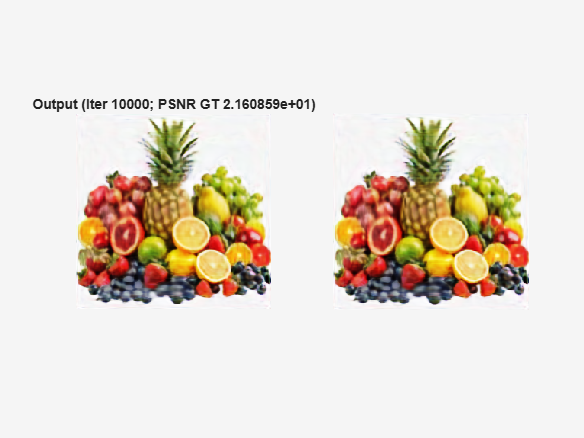

% Load the variables from the MAT-file
data = load('saved_model_and_image_denoising.mat');

% Access the saved image
saved_img = data.final_image;
imshow(saved_img);


% Access the restored network
restored_net = data.net;

## Saved Results Side By Side

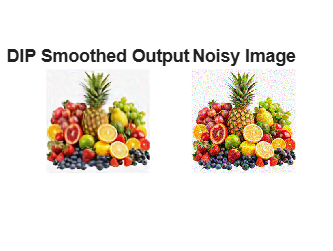

figure;
subplot(1,2,1); imshow(saved_img); title('DIP Smoothed Output');
subplot(1,2,2); imshow(noisyImg); title('Noisy Image');